## Project: Machine Design 1

## Computer aided design of Helical Springs. The final  design must give a dimensioned layout of the Helical Springs along with all design parameters.

### Preliminary report submission & discussion: 19-10-2023 

### Final report submission & presentation: 01-11-2023

**Name: **Priyank Mitram Singh

**Roll.No: **21BME099

Copy right @ PM Singh

## **1. Design for Static Load**

#### Define Requirments:

    Estimated  the maximum spring force (P) :

P=1500

P = 1500

    Required deflection (∂) :

deflection=50

deflection = 50

    Ultimate tensile strength (Sut) of selected material:

UTS=1090

UTS = 1090

    Modulus of rigidity (G):

G = 81370

G = 81370

     spring index  (C) : 

C=8

C = 8

#### Calculations:

    Permissible shear stress :

tau = 0.5*UTS

tau = 545

    Wahl factor (K) :

K = ((4*C-1)/(4*C-4))+(0.615/C)

K = 1.1840

    Wire diameter (d):

d = round(sqrt((8*K*P*C)/(pi*tau)))

d = 8

    Mean coil diameter (D) :

D = C*d

D = 64

    Number of active coils (N):

N = round((deflection*G*d^4)/(8*P*D^3))

N = 5

%  for square and grounded spring
Nt = N+2

Nt = 7

    Solid length :

solid_length = Nt*d

solid_length = 56

    Actual deflection of the spring

actual_deflection = (8*P*N*D^3)/(G*d^4)

actual_deflection = 47.1918

    The total axial gap  between coils:

total_gap = (Nt-1)*1

total_gap = 6

    Free length of the spring:

free_length = solid_length + total_gap + deflection

free_length = 112

    Pitch of the coil :

pitch = free_length/(Nt-1)

pitch = 18.6667

    Rate of spring (k) :

k = (G*d^4)/(8*N*D^3)

k = 31.7852

## **2. Design for **Fluctuating Load

Pmax =1000

Pmax = 1000

Pmin =400

Pmin = 400

tau_y =770

tau_y = 770

tau_e =350

tau_e = 350

fos_n =1.25

fos_n = 1.2500

--------------

Pm = (Pmax+Pmin)/2

Pm = 700

Pa = (Pmax-Pmin)/2

Pa = 300

Shear Stress Factor :

Ks = 1+0.5/C

Ks = 1.0625

------------------

tau_m = (8*Ks*Pm*D)/(pi*d^3)

tau_m = 236.7430

tau_a = (8*K*Pa*D)/(pi*d^3)

tau_a = 113.0654

-------------------

d_f = sqrt(((8*C*fos_n)/pi)*(((Ks*Pm-K*Pa)/tau_y)+(2*K*Pa)/tau_e))

d_f = 8.0335

D_f = C*d_f

D_f = 64.2678

N_f = (deflection*G*d_f^4)/(8*Pmax*D^3)

N_f = 8.0801

Nt_f = N_f+2

Nt_f = 10.0801

free_length_f = Nt_f+deflection+0.15*deflection

free_length_f = 67.5801

## **3. CAD**

**--------------------**

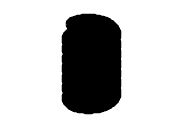

r_in = (D-d)/2;
r_out  = (D+d)/2;
L = free_length;
loop = Nt;


frac = 20;
nNodes = 50;
nCS = 1400;

plotOrigin([-2 2],[-2 2],[-1 6],[0 0 0]); axis off

alpha = loop*360 + frac;


th = linspace(0,2*pi,nNodes);
r = 0.5*(r_out-r_in)*ones(1,nNodes);
z = r.*cos(th);
y = r.*sin(th)+r_in+0.5*(r_out-r_in);
x = zeros(1,nNodes);

dz = linspace(0,L,nCS);
phi = linspace(0,alpha,nCS);
X =[];
Y =[];
Z =[];
for i=1:nCS
    temp_CS = rotationMatrix('z',phi(i)) * [x;y;z];
    X =[X; temp_CS(1,:)];
    Y =[Y; temp_CS(2,:)];
    Z =[Z; temp_CS(3,:)+dz(i)];
    plot3(X(i,:),Y(i,:),Z(i,:),'ok');
end
% solidifing 
[X, Y, Z] = get_plates(X, Y, Z, nNodes, r_out, r_in, alpha, L) ;
% doing surfacing in adjecent rings
surf(X,Y,Z)

Plot3ToSTL(X,Y,Z)    % Export

**Solidifier function:**

function [X, Y, Z] = get_plates(X, Y, Z, nNodes, r_out, r_in, alpha, L) 
plate1 = [0; 0.5*(r_out-r_in) + r_in; 0];
plate2 = rotationMatrix('z', alpha)*plate1;
plate1 = repmat(plate1, 1, nNodes); 
plate2 = repmat (plate2, 1, nNodes);
X = [plate1(1,:); X; plate2(1,:)]; 
Y = [plate1(2,:); Y; plate2(2,:)];
Z = [plate1(3,:); Z; plate2(3,:) + L];
end